srcDir = "..\srcImages\";
building_dark = readraw(srcDir + "building.raw");

    "→Retrieving Image "    "..\srcImages\building.raw"    " ..."



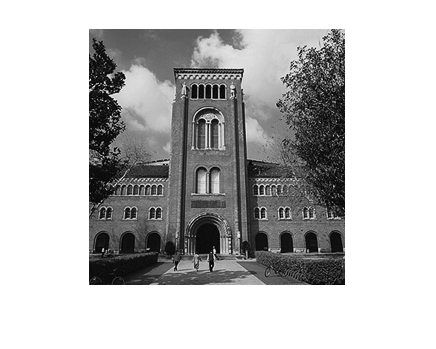


building_contrast = contrastLinearScaled(building_dark);
imshow(building_contrast);

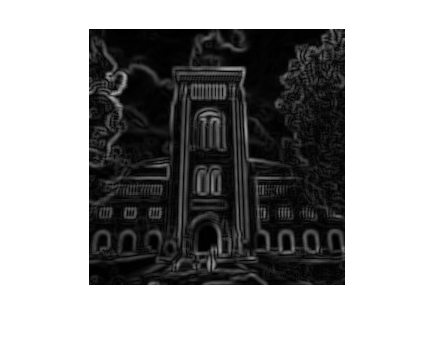


edgeMap = sobelEdgeMap(building_contrast, 0.15);

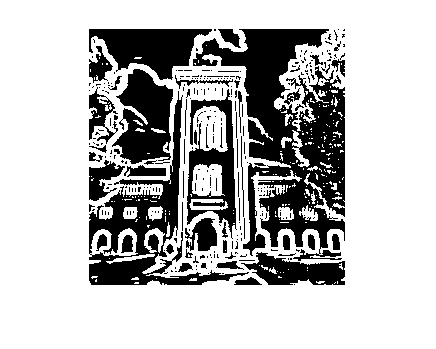

imshow(edgeMap);





building_noise = readraw(srcDir + "building_noise.raw");

    "→Retrieving Image "    "..\srcImages\building_noise.raw"    " ..."



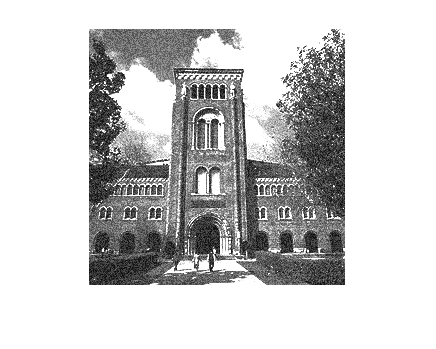

imshow(building_noise);

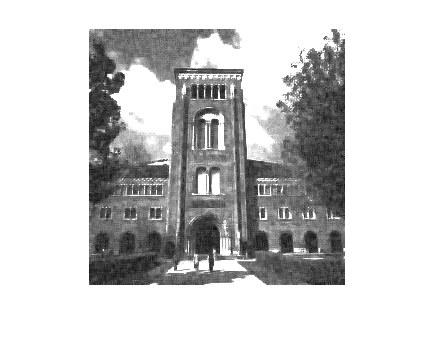


building_blur = applyMedianFilter(building_noise, 5);
%imshow(building_blur);
%building_blur = applyMedianFilter(building_blur, 5);
%building_blur = gaussBlur5x5(building_blur);
imshow(building_blur);

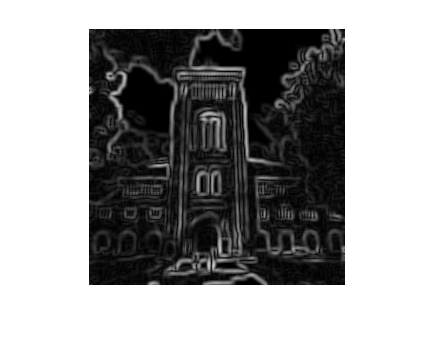


edgeMap = sobelEdgeMap(building_blur, 0.2);

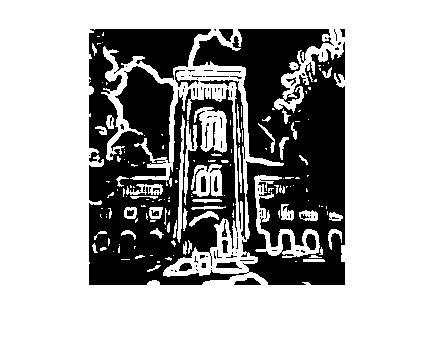

imshow(edgeMap);